#### **Linear Mixed-Effects Models** (from analyze_HDIs_across_link_densities.m)

This script implements a series of LMMs to compare across different treatment groups and time points, while controlling for covariates such as age, sex, avg pain, head motion.

I'm really only interested only in the patient vs heathy comparison - but I'm plotting first 6 model outputs from model_olp4cbp_wrapper & model_olp4cbp_outcomes functions.

today = datestr(datetime("today"),'yymmdd'); % for saving files at the end

%% load all the HDI results files, for all link densities
which_ref = 'paingen'

which_ref = 'paingen'

% hdi_fnames = filenames('Data/paingen as ref/*_HDI_res_paingen_*mat')
hdi_fnames = filenames(['Data/' which_ref ' as ref/*_HDI_res_' which_ref '_*mat'])

hdi_fnames = 5×1 cell array
    {'Data/paingen as ref/240326_HDI_res_paingen_0.1.mat'}
    {'Data/paingen as ref/240326_HDI_res_paingen_0.2.mat'}
    {'Data/paingen as ref/240326_HDI_res_paingen_0.3.mat'}
    {'Data/paingen as ref/240327_HDI_res_paingen_0.4.mat'}
    {'Data/paingen as ref/240327_HDI_res_paingen_0.5.mat'}


hdis = struct();
for i=1:length(hdi_fnames)
    load(hdi_fnames{i}, 'bs')
    
    thresh = strsplit(hdi_fnames{i}, '0.');
    thresh = thresh{2}(1:end-4);
    
    if contains(hdi_fnames{1}, 'paingen')
        hdis.(['link_dens_' thresh]) = bs.HDIs.regions;
    else
        hdis.(['link_dens_' thresh]) = bs.HDIs;
    end
end

title_text = 'T Stats Heatmap of Model: p\_vs\_hc - betweenness\_bin'

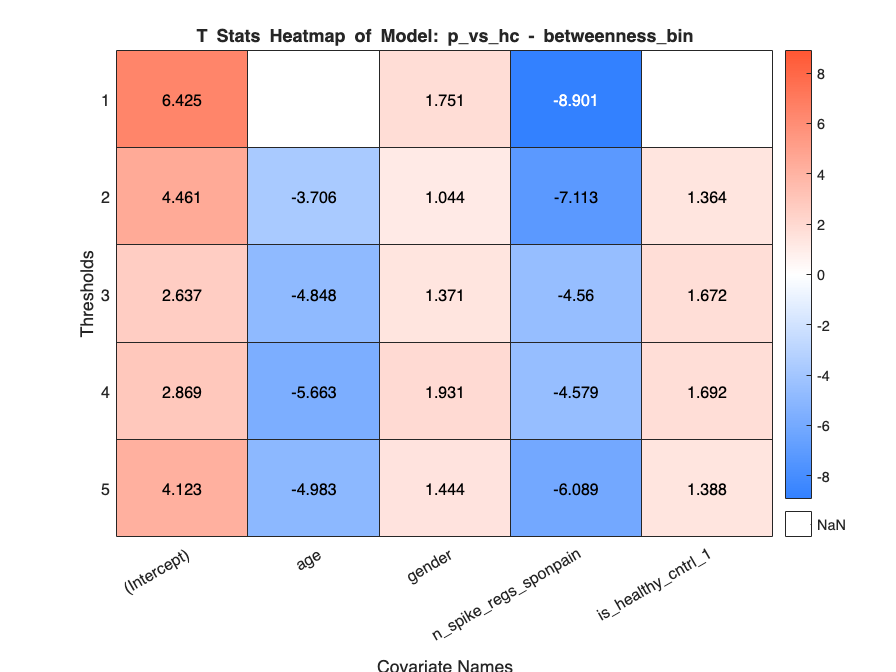

title_text = 'T Stats Heatmap of Model: p\_vs\_hc - clustercoef\_bin'

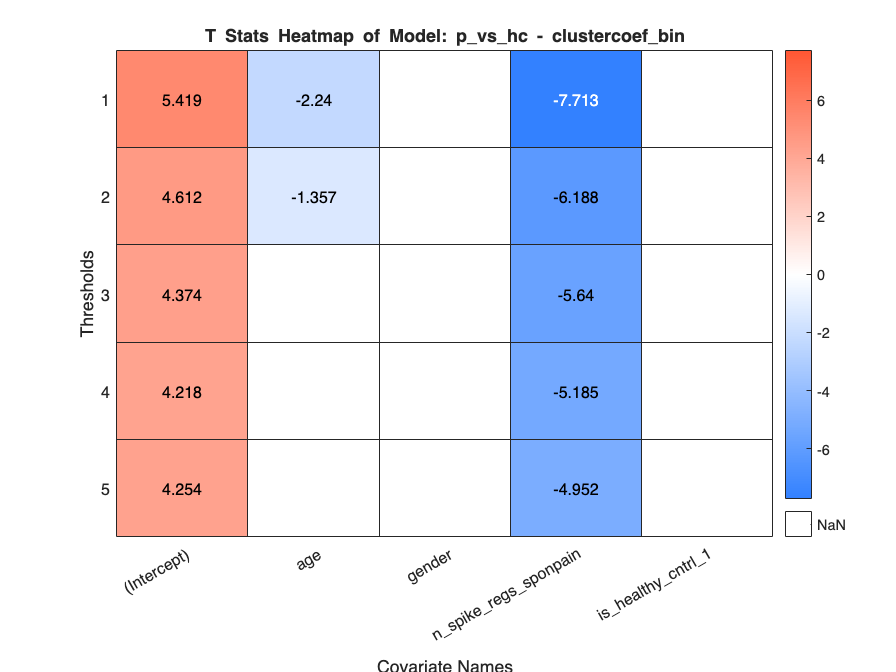

% remove participants with low data quality
wh_keep = bs.data_quality.median_corr < std(bs.data_quality.median_corr)*3;
% X is metadata from subject with HQ data
X = bs.subject_metadata(wh_keep,:);

opts = {'noverbose' 'standardize' 'sponpain_motion'};
metrics = {'betweenness_bin', 'clustercoef_bin'};
for m=1:length(metrics)
    % create outcome var -- one thresh level in each col
    threshs = fieldnames(hdis);
    y = [];
    for thr=1:length(threshs)
        y(:,thr) = hdis.(threshs{thr}).(metrics{m})(wh_keep);
    end
    

    % Define model names
    model_names = {'group_by_time', 'three_groups_by_time', 'prt_vs_combined', 'p_vs_hc', 'simple_time1', 'simple_time2'};
    % Initialise structure to store model outputs
    model_struct = struct('outputs', {}, 'names', {});
    % Call the model_olp4cbp_wrapper LMM and store outputs in a cell array
    [out{1}, out{2}, out{3}, out{4}, out{5}, out{6}] = model_olp4cbp_wrapper(y, X, opts{:});
    % Assign outputs and names to the structure
    for j = 1:numel(model_names)
        model_struct(j).outputs = out{j};
        model_struct(j).names = model_names{j};
    end

    model = model_struct(4); % p_vs_hc
    % Extracting data
    t_statistics = model.outputs.tStat;
    t_statistics(abs(t_statistics) < 1) = NaN;
    covariate_names = model.outputs.names;
   
    
    % Define RGB values for the given hex codes
    hex_codes = {'#3381FF', '#FFFFFF', '#FF5733'};
    rgb_values = sscanf(cat(2, hex_codes{:}), '#%2x%2x%2x', [3, numel(hex_codes)])' / 255;
    custom_colormap = interp1(linspace(0, 1, numel(hex_codes)), rgb_values, linspace(0, 1, 256));

    max_abs_value = max(abs(t_statistics), [], 'all');

    % Creating heatmap
    figure;
    heatmap(regexprep(covariate_names, '_', '\\_'), 1:size(t_statistics, 2), t_statistics', 'ColorLimits', [-max_abs_value, max_abs_value], 'MissingDataColor', [1 1 1]);
    
    % Customizing heatmap
    colormap(custom_colormap); % You can change the colormap if needed
    colorbar;
    
    % Setting axis labels and title
    xlabel('Covariate Names');
    ylabel('Thresholds');
    title_text = regexprep(['T Stats Heatmap of Model: ' model.names ' - ' metrics{m}], '_', '\\_')
    title(title_text);

    filename = ['Graphs/' which_ref ' LMM/' today '_' model.names '_' metrics{m} '.png'];
    saveas(gcf, filename);

    snapnow
end